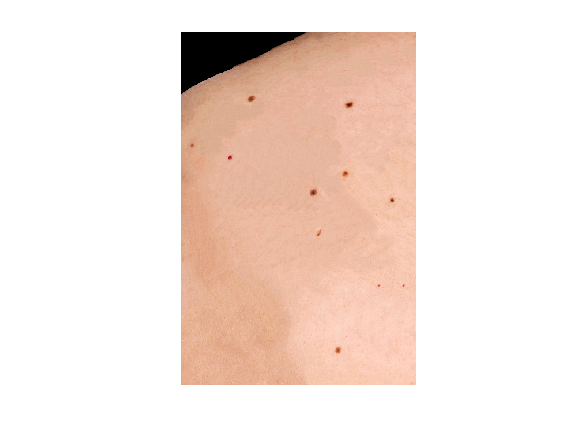

% Clear workspace & command window
clc;
clear all;

% ---------------------------------
% Part 1: Remove non-skin area
% ---------------------------------
% Read image
[filename, path] = uigetfile('*.*', 'Select input image');
I = imread([path filename]);

% -----------------------
% Convert to YCbCr
YCbCr = rgb2ycbcr(I);
% -----------------------
% Split each channel
Y=YCbCr( :,:,1);
Cb=YCbCr( :,:,2);
Cr=YCbCr( :,:,3);

% Threshold the skin from non-skin
skinplace = (93<Cb) & (Cb<136) & (138<Cr) & (Cr<175);

% -----------------------
% Fill small holes (disease spots)
imgFilled=imfill(skinplace,'holes');

% Perform morphological operation
se=strel('disk',15);
imgOpen = imopen(imgFilled, se);

% Extract the only biggest blob
imgBigBlob = bwareafilt(imgOpen, 1);

% -----------------------
% Denoise using Median filter
imgFiltered = medfilt2(imgBigBlob);

% -----------------------
% Binary filtered image for output mask
Bw = imgFiltered;

% -----------------------
% Initialize output masked image based on input image.
maskedRGBImage = I;

% -----------------------
% Create RGB mask (Remove background)
maskedRGBImage(repmat(~Bw,[1 1 3])) = 0;

figure; imshow(maskedRGBImage);

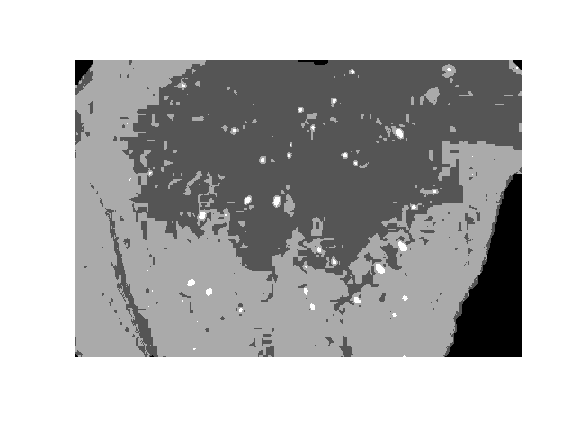


% ---------------------------------
% Part 2: Segmentation using KMeans
% ---------------------------------
% Convert to L*a*b color space
lab_he = rgb2lab(maskedRGBImage);

% Extract first channel (L)
ab = lab_he(:, :, 2:3);

% Convert to data type single
ab = im2single(ab);

% Perform clustering using K-Means
nColors = 4;
pixel_labels = imsegkmeans(ab, nColors, "NumAttempts", 5);
imshow(pixel_labels, []);

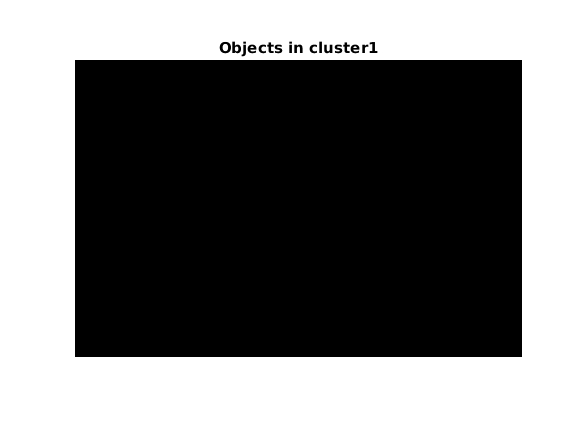


% For sorting clusters and centers
[cluster_idx, cluster_center] = imsegkmeans(ab, nColors, "NumAttempts", 5);

% Display each cluster with their objects
mask1 = pixel_labels == 1;
cluster1 = maskedRGBImage .* uint8(mask1);
imshow(cluster1); title('Objects in cluster1');

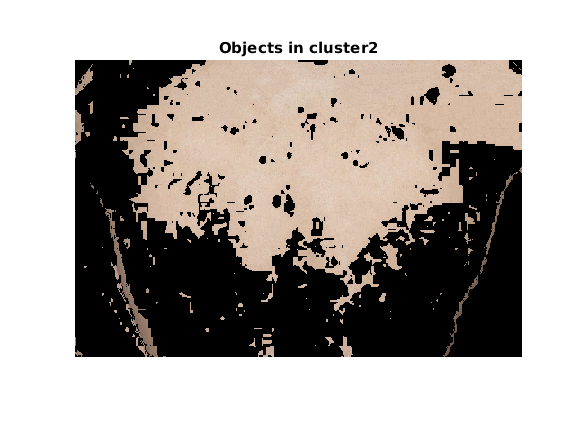


% Display second cluster's objects
mask2 = pixel_labels == 2;
cluster2 = maskedRGBImage .* uint8(mask2);
imshow(cluster2); title('Objects in cluster2');

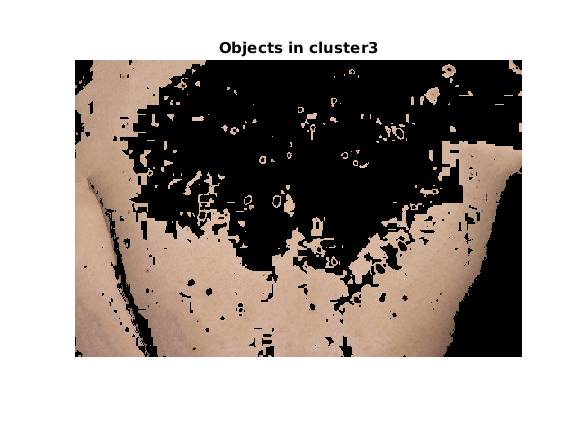


% Display third cluster's objects
mask3 = pixel_labels == 3;
cluster3 = maskedRGBImage .* uint8(mask3);
imshow(cluster3); title('Objects in cluster3');

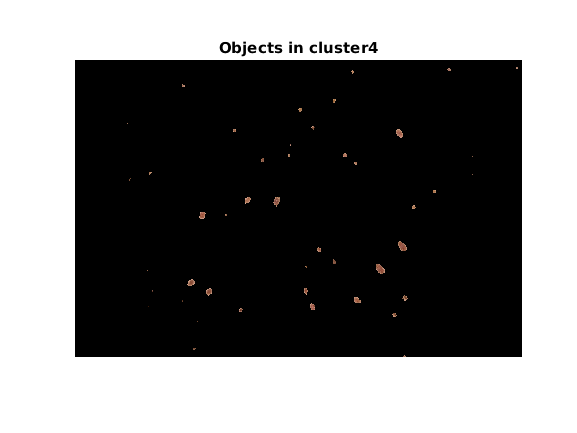


% Display fourth cluster's objects
mask4 = pixel_labels == 4;
cluster4 = maskedRGBImage .* uint8(mask4);
imshow(cluster4); title('Objects in cluster4');

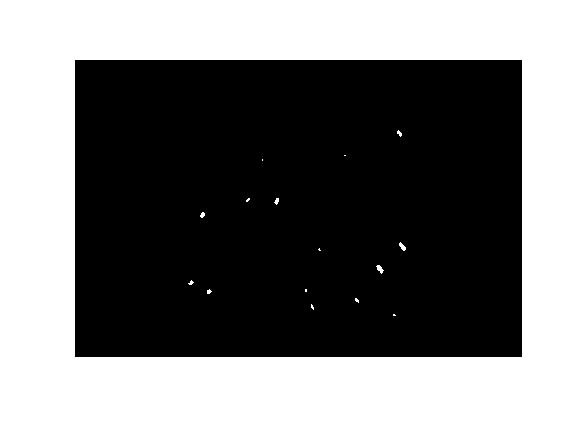


% Sort clusters to find the desired cluster automatically
mean_cluster_value = mean(cluster_center,2);
[tmp, idx] = sort(mean_cluster_value);
DesiredClusterNum = idx(4);

if idx(4) == 1
    clstr = cluster1;
    rIm = cluster1(:, :, 1);
elseif idx(4) == 2
    clstr = cluster2;
    rIm = cluster2(:, :, 1);
elseif idx(4) == 3
    clstr = cluster3;
    rIm = cluster3(:, :, 1);
else
    clstr = cluster4;
    rIm = cluster4(:, :, 1);
end

% Remove noise using Median filter
iDenoised = medfilt2(rIm);

% Fill gaps in the denoised image
iFill = imfill(iDenoised);

% Enhance contrast to get clear objects in binary image
iCont = imadjust(iFill);

% Convert the grayscale image to binary
binaryImage = im2bw(iCont);

% Perform Erode to get the real objects and smooth them
se = strel('disk', 3);
ierd = imerode(binaryImage, se);

% Perform Dilate to enlarge real objects
sD = strel('disk', 1);
imD = imdilate(ierd, sD);

% Get round shaped objects
labeledImage = bwlabel(imD);
imshow(labeledImage);

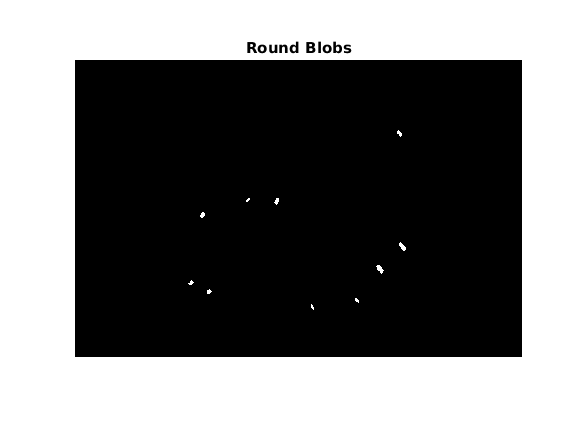

props = regionprops(imD, 'Area', 'Perimeter');
allAreas = [props.Area];
allPerimeters = [props.Perimeter];
circularities = allPerimeters.^2./(4*pi*allAreas);
circleIdx = (circularities > 0.7) & (circularities < 1.5);
areaIdx = ([props.Area] > 30) & ([props.Area] < 1437);
roundindexes = find(circleIdx & areaIdx);
roundBlobs = imclearborder(ismember(labeledImage, roundindexes));
imshow(roundBlobs), title('Round Blobs');

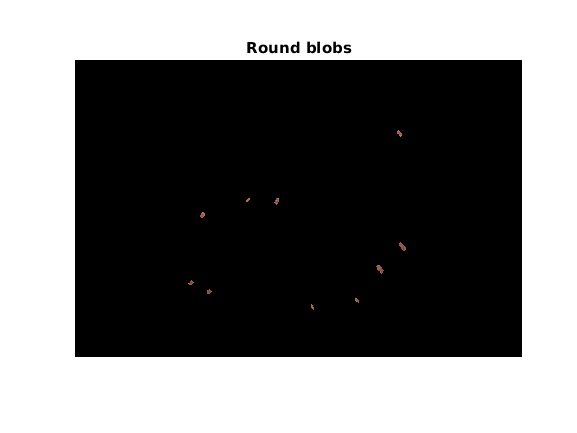


mskRgbImg = bsxfun(@times, clstr, cast(roundBlobs, 'like', clstr));
imshow(mskRgbImg), title('Round blobs');

% % ----------------------------------------------
% % Part 3: Feature extraction using mean and glcm
% % ----------------------------------------------
% roundBlobs = regionprops(roundBlobs, 'BoundingBox');
% for k = 1 : length(roundBlobs)
%     thisBB = roundBlobs(k).BoundingBox;
%     crop_blob=imcrop(clstr,[thisBB(1),thisBB(2),thisBB(3),thisBB(4)]);
%     resize_blob=imresize(crop_blob,[thisBB(3) thisBB(4)]);
%     
% %     Calculate mean of color spaces
%     redChannel = resize_blob(:, :, 1);
%     greenChannel = resize_blob(:, :, 2);
%     blueChannel = resize_blob(:, :, 3);
% %     Get mean of R, G, and B
%     meanR = mean2(redChannel);
%     meanG = mean2(greenChannel);
%     meanB = mean2(blueChannel); 
%     
%     HSVimage = rgb2hsv(resize_blob);
%     H_component = HSVimage(:,:,1);
%     S_component = HSVimage(:,:,2);
%     V_component = HSVimage(:,:,3);
% %     Get mean of Hue, Saturation, and Value
%     meanH = mean(H_component(:));
%     meanS = mean(S_component(:));
%     meanV = mean(V_component(:));
%     
%     YCbCrimage = rgb2ycbcr(resize_blob);
%     Y_component = YCbCrimage(:,:,1);
%     Cb_component = YCbCrimage(:,:,2);
%     Cr_component = YCbCrimage(:,:,3);
% %     Get mean of Y, Cb, and Cr
%     meanY = mean2(Y_component);
%     meanCb = mean2(Cb_component);
%     meanCr = mean2(Cr_component);
% 
%     Lab = rgb2lab(resize_blob);
%     L = Lab(:,:,1);
%     a = Lab(:,:,2);
%     b = Lab(:,:,3);
% %     Get mean of L, a, and b
%     meanL = mean2(L);
%     meanLA = mean2(a);
%     meanLB = mean2(b);
%     
%     gray_img = rgb2gray(resize_blob);
%     meanGray = mean2(gray_img);
%     
%     Class = 1;
%     
% %     Calculate GLCM and extract texture features
%     gray_blob = rgb2gray(resize_blob);
%     offsets = [0 1; -1 1;-1 0;-1 -1];
%     glcm = graycomatrix(gray_blob, 'GrayLimits', [], 'Offset', offsets, 'Symmetric', true);
%     stats = graycoprops(glcm);
%     avgCont = mean(stats.Contrast);
%     avgCorrel = mean(stats.Correlation);
%     avgEnergy = mean(stats.Energy);
%     avgHomogen = mean(stats.Homogeneity);
%     Feats = [avgCont, avgCorrel, avgEnergy, avgHomogen, meanR, meanG, meanB, meanH, meanS, meanV, meanY, meanCb, meanCr, meanL, meanLA, meanLB, meanGray, Class];
%     glcm_data(k, :) = Feats(:);
%     
%     m = matfile('BirthmarksData.mat', 'Writable', true);
%     if isprop(m, 'BirthmarksData')
%         s = size(m, 'BirthmarksData');
%         m.BirthmarksData(s(1)+1, :) = glcm_data(k, :);    
%     else
%         m.BirthmarksData = glcm_data(k, :);
%     end
%     load('BirthmarksData.mat');
%     writematrix(BirthmarksData, 'BirthmarksData.csv');
% end